MEM703039 

S1.2023 - 2024

Lab 5

Student ID

Date: 2024/09/20

 **Bài 1 (8 điểm) – Design problem**

Cho Robot như hình vẽ (Given the manipulator)

            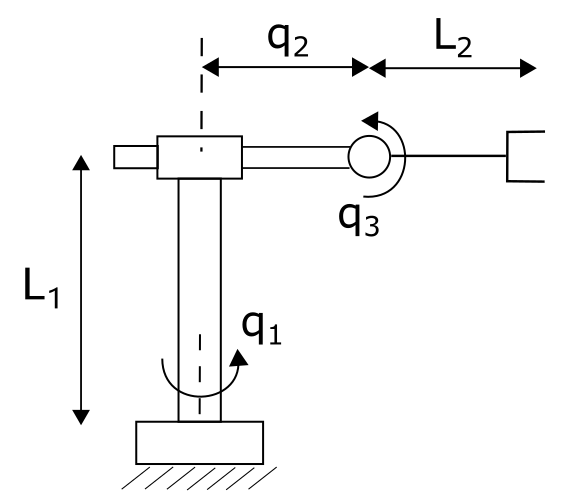                  

a. Gắn các hệ trục tọa độ lên sơ đồ động học (Determine the frames on the links) – *3 points*

b. Xây dựng bảng D-H (Establish the D-H table) – *1 points*

c. Xây dựng ma trận biến đổi  (Derive the transformation matrices) – *1 points* 

d. Giải bài toán động học thuận và viết hệ phương trình biểu diễn tọa độ và hướng của khâu cuối (Calculation the forward kinematics and determine the orientation and the direction of the end-effector) – *3 points*

**Bài 2 (2 điểm) **

Tính ma trận Jacobi tịnh tiến của ma trận biến đổi thuần nhất  trong câu 1. 

Calculate the Jacobian matrix.

**Bài 1**

*a. Attachment of the frame*

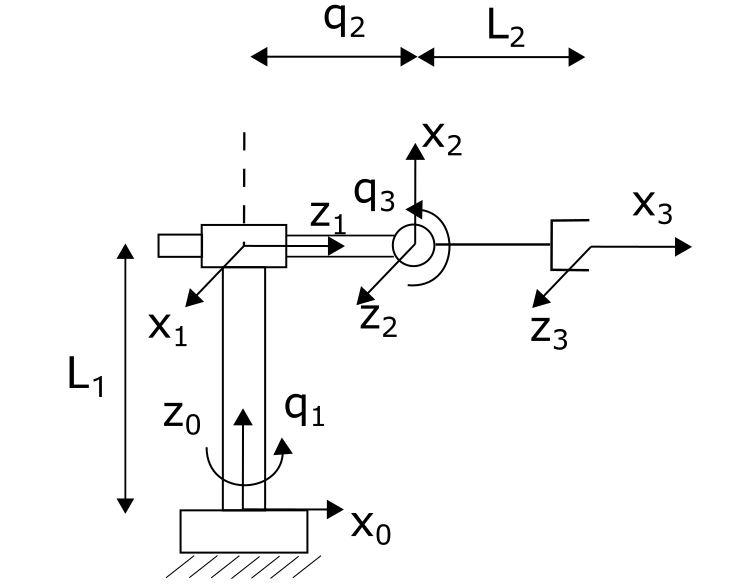

*b. D-H table*

             a   |    alpha    |  d         | theta   

0 ->1    0   |    -pi/2      |   L1      |   q1

1 ->2    0   |    -pi/2      |   q2      |    pi/2

2-> 3    L2 |       0        |   0        |   q3

*c. Homogeneous transformatrion matrices *

clc;
clear;

% Thông số Denavit-Hartenberg (DH)
syms a1 a2 a3 alpha1 alpha2 alpha3 d1 d2 d3 theta1 theta2 theta3
syms L1 L2 q1 q2 q3
a1 = sym(0)

$$a1 = 0$$

a2 = sym(0)

$$a2 = 0$$

a3 = sym(L2)

$$a3 = L_{2}$$


alpha1 = sym(-pi/2)

$$alpha1 = -\frac{\pi }{2}$$

alpha2 = sym(-pi/2)

$$alpha2 = -\frac{\pi }{2}$$

alpha3 = sym(0)

$$alpha3 = 0$$


d1 = sym(L1)

$$d1 = L_{1}$$

d2 = sym(q2)

$$d2 = q_{2}$$

d3 = sym(0)

$$d3 = 0$$


theta1 = sym(q1)

$$theta1 = q_{1}$$

theta2 = sym(-pi/2)

$$theta2 = -\frac{\pi }{2}$$

theta3 = sym(q3)

$$theta3 = q_{3}$$

% Hàm chuyển đổi DH
DH = @(a, alpha, d, theta) [cos(theta), -sin(theta)*cos(alpha),  sin(theta)*sin(alpha), a*cos(theta);
                            sin(theta),  cos(theta)*cos(alpha), -cos(theta)*sin(alpha), a*sin(theta);
                                  0,             sin(alpha),             cos(alpha),            d;
                                  0,                    0,                     0,            1];

                              
% Ma trận chuyển đổi từ hệ quy chiếu khớp này sang khớp tiếp theo
T1 = DH(a1, alpha1, d1, theta1); % Ma trận chuyển đổi từ khớp 1 đến khớp 2
T2 = DH(a2, alpha2, d2, theta2);  % Ma trận chuyển đổi từ khớp 2 đến khớp 3
T3 = DH(a3, alpha3, d3, theta3);  % Ma trận chuyển đổi từ khớp 3 đến khâu thao tác

disp('Ma trận chuyển đổi đồng nhất từ khâu 0 đến khâu 1:');

Ma trận chuyển đổi đồng nhất từ khâu 0 đến khâu 1:


disp(T1);

$$\left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & -\sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & 0 & \cos\left(q_{1}\right) & 0\\ 0 & -1 & 0 & L_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


disp('Ma trận chuyển đổi đồng nhất từ khâu 1 đến khâu 2:');

Ma trận chuyển đổi đồng nhất từ khâu 1 đến khâu 2:


disp(T2);

$$\left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ -1 & 0 & 0 & 0\\ 0 & -1 & 0 & q_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


disp('Ma trận chuyển đổi đồng nhất từ khâu 2 đến khâu 3:');

Ma trận chuyển đổi đồng nhất từ khâu 2 đến khâu 3:


disp(T3);

$$\left(\begin{array}{cccc} \cos\left(q_{3}\right) & -\sin\left(q_{3}\right) & 0 & L_{2}\,\cos\left(q_{3}\right)\\ \sin\left(q_{3}\right) & \cos\left(q_{3}\right) & 0 & L_{2}\,\sin\left(q_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Ma trận biến đổi đồng nhất từ khâu 0 đến khâu cuối
T = simplify(T1* T2 * T3);
disp('Ma trận chuyển đổi đồng nhất:');

Ma trận chuyển đổi đồng nhất:


disp(T);

$$\begin{array}{l} \left(\begin{array}{cccc} \sin\left(q_{1}\right)\,\sin\left(q_{3}\right) & \cos\left(q_{3}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & -\sin\left(q_{1}\right)\,\sigma_{1}\\ -\cos\left(q_{1}\right)\,\sin\left(q_{3}\right) & -\cos\left(q_{1}\right)\,\cos\left(q_{3}\right) & \sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\sigma_{1}\\ \cos\left(q_{3}\right) & -\sin\left(q_{3}\right) & 0 & L_{1}+L_{2}\,\cos\left(q_{3}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=q_{2}-L_{2}\,\sin\left(q_{3}\right) \end{array}$$

*d. Bài toán động học thuận*

% Ma trận cosin chỉ hướng
disp('Ma trận cosin chỉ hướng');

Ma trận cosin chỉ hướng


R = T(1:3, 1:3)

$$R = \left(\begin{array}{ccc} \sin\left(q_{1}\right)\,\sin\left(q_{3}\right) & \cos\left(q_{3}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\\ -\cos\left(q_{1}\right)\,\sin\left(q_{3}\right) & -\cos\left(q_{1}\right)\,\cos\left(q_{3}\right) & \sin\left(q_{1}\right)\\ \cos\left(q_{3}\right) & -\sin\left(q_{3}\right) & 0 \end{array}\right)$$


% Tọa độ điểm thao tác cuối
disp('Tọa độ điểm thao tác cuối');

Tọa độ điểm thao tác cuối


position = T(1:3, 4)

$$position = \left(\begin{array}{c} -\sin\left(q_{1}\right)\,\left(q_{2}-L_{2}\,\sin\left(q_{3}\right)\right)\\ \cos\left(q_{1}\right)\,\left(q_{2}-L_{2}\,\sin\left(q_{3}\right)\right)\\ L_{1}+L_{2}\,\cos\left(q_{3}\right) \end{array}\right)$$

xE = position (1,1)

$$xE = -\sin\left(q_{1}\right)\,\left(q_{2}-L_{2}\,\sin\left(q_{3}\right)\right)$$

yE = position (2,1)

$$yE = \cos\left(q_{1}\right)\,\left(q_{2}-L_{2}\,\sin\left(q_{3}\right)\right)$$

zE = position (3,1)

$$zE = L_{1}+L_{2}\,\cos\left(q_{3}\right)$$

**Bài 2: Tính ma trận Jacobi**

J = jacobian([xE; yE; zE], [q1,q2,q3])

$$J = \left(\begin{array}{ccc} -\cos\left(q_{1}\right)\,\left(q_{2}-L_{2}\,\sin\left(q_{3}\right)\right) & -\sin\left(q_{1}\right) & L_{2}\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\\ -\sin\left(q_{1}\right)\,\left(q_{2}-L_{2}\,\sin\left(q_{3}\right)\right) & \cos\left(q_{1}\right) & -L_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\\ 0 & 0 & -L_{2}\,\sin\left(q_{3}\right) \end{array}\right)$$